%% 16-QAM Transceiver with NI USRP-2900 (With Full Sync Pipeline)
clear; clc; close all;

%% 1. System Parameters
centerFreq   = 915e6;          % 915 MHz ISM band
sampleRate   = 1e6;            % 1 Msps
txGain       = 15;             % dB (Lowered to avoid Tx amplifier saturation)
rxGain       = 25;             % dB
usrpIP       = '310738C'; % USRP Serial/IP Address

M            = 16;
k            = log2(M);        
numSymbols   = 4000;           % Higher frame length helps synchronizer lock
sps          = 4;              % Samples per symbol

%% 2. Custom 16-QAM Modulation
txBits = randi([0 1], numSymbols * k, 1);
txSymbols = custom_qammod_16(txBits);

% Pulse Shaping (Root Raised Cosine)
rolloff = 0.35;
filterSpanInSymbols = 8;
rrcFilter = rcosdesign(rolloff, filterSpanInSymbols, sps, 'sqrt');
txWaveform = upfirdn(txSymbols, rrcFilter, sps);

%% 3. Hardware Setup
try
    txRadio = comm.SDRuTransmitter(...
        'Platform',             'B200', ...
        'SerialNum',            usrpIP, ...
        'CenterFrequency',      centerFreq, ...
        'Gain',                 txGain, ...
        'MasterClockRate',      32e6, ...
        'InterpolationFactor',  32e6 / sampleRate);

    rxRadio = comm.SDRuReceiver(...
        'Platform',             'B200', ...
        'SerialNum',            usrpIP, ...
        'CenterFrequency',      centerFreq, ...
        'Gain',                 rxGain, ...
        'MasterClockRate',      32e6, ...
        'DecimationFactor',     32e6 / sampleRate, ...
        'OutputDataType',       'double', ...
        'SamplesPerFrame',      length(txWaveform) * 4);
catch ME
    error('USRP initialization failed: %s', ME.message);
end

%% 4. Transmit & Receive Execution
disp('Transmitting and receiving over USRP 2900...');

Transmitting and receiving over USRP 2900...


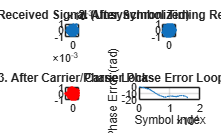


% Continuous transmission loop
for i = 1:50
    txRadio(txWaveform);
end

[rxWaveform, len, overflow] = rxRadio();

release(txRadio);
release(rxRadio);

if len == 0
    error('No samples received from USRP. Check connection.');
end

%% 5. Receiver Signal Processing Chain
% Step A: Automatic Gain Control (AGC) - Normalizes signal level
agc = comm.AGC('DesiredOutputPower', 1);
rxAGC = agc(rxWaveform);

% Step B: Matched Filtering (RRC Receive Filter)
rxFiltered = upfirdn(rxAGC, rrcFilter, 1);

% Step C: Symbol Timing Synchronization (Gardner Algorithm)
symbolSync = comm.SymbolSynchronizer(...
    'SamplesPerSymbol', sps, ...
    'DampingFactor', 1, ...
    'NormalizedLoopBandwidth', 0.01);
rxSyncedSymbols = symbolSync(rxFiltered);

% Step D: Carrier Frequency & Phase Synchronization
carrierSync = comm.CarrierSynchronizer(...
    'Modulation', 'QAM', ...
    'SamplesPerSymbol', 1, ...
    'DampingFactor', 0.707, ...
    'NormalizedLoopBandwidth', 0.01);
[rxCorrectedSymbols, phError] = carrierSync(rxSyncedSymbols);

% Step E: Gain re-scaling for custom decision boundaries
rxFinalSymbols = rxCorrectedSymbols / sqrt(mean(abs(rxCorrectedSymbols).^2));

% Step F: Demodulation
% Trim transient warm-up symbols from lock-in period
transient = 200; 
validSymbols = rxFinalSymbols(transient+1:end);
rxBits = custom_qamdemod_16(validSymbols);

%% 6. Diagnostic Visualization
figure('Name', 'USRP Signal Rehabilitation', 'NumberTitle', 'off');

subplot(2,2,1);
plot(real(rxWaveform), imag(rxWaveform), '.');
grid on; axis square;
title('1. Raw Received Signal (Unsynchronized)');

subplot(2,2,2);
plot(real(rxSyncedSymbols), imag(rxSyncedSymbols), '.');
grid on; axis square;
title('2. After Symbol Timing Recovery');

subplot(2,2,3);
plot(real(rxCorrectedSymbols), imag(rxCorrectedSymbols), 'r.');
grid on; axis square;
title('3. After Carrier/Phase Lock');

subplot(2,2,4);
plot(phError);
grid on;
title('Carrier Phase Error Loop Lock');
xlabel('Symbol Index'); ylabel('Phase Error (rad)');


%% --- Custom Modulation / Demodulation Functions ---
function symbols = custom_qammod_16(bits)
    bitsMatrix = reshape(bits, 4, []).';
    I = map_bits_to_pam4(bitsMatrix(:, 1:2));
    Q = map_bits_to_pam4(bitsMatrix(:, 3:4));
    symbols = (I + 1i * Q) / sqrt(10);
end

function pam4 = map_bits_to_pam4(bit_pairs)
    idx = bit_pairs(:,1)*2 + bit_pairs(:,2);
    pam_table = [-3; -1; 3; 1];
    pam4 = pam_table(idx + 1);
end

function bits = custom_qamdemod_16(symbols)
    raw_symbols = symbols * sqrt(10);
    I = real(raw_symbols);
    Q = imag(raw_symbols);
    
    I_bits = map_pam4_to_bits(I);
    Q_bits = map_pam4_to_bits(Q);
    
    bitsMatrix = [I_bits, Q_bits];
    bits = reshape(bitsMatrix.', [], 1);
end

function bit_pairs = map_pam4_to_bits(val)
    n = length(val);
    bit_pairs = zeros(n, 2);
    for i = 1:n
        if val(i) < -2
            bit_pairs(i, :) = [0, 0];
        elseif val(i) < 0
            bit_pairs(i, :) = [0, 1];
        elseif val(i) < 2
            bit_pairs(i, :) = [1, 1];
        else
            bit_pairs(i, :) = [1, 0];
        end
    end
end